Messdaten:

x = [1 2 3 4]'

x =      1
     2
     3
     4


y = [10 8 9 11]'

y =     10
     8
     9
    11


Modellgleichung:


$$p(t) = \alpha_1t + \alpha_0$$


Systemmatrix:


$$\left(\begin{array}{cc}
1&1\\
2&1\\
3&1\\
4&1\\
\end{array}\right)

\left(\begin{array}{c}
\alpha_1\\
\alpha_0\\
\end{array}\right)

\approx 

\left(\begin{array}{c}
10\\
8\\
9\\
11\\
\end{array}\right)$$


vs = [x ones(size(x))]

vs =      1     1
     2     1
     3     1
     4     1


QR-Zerlegung

[Q, R] = qr(vs);

Löse:


$$R \left( \begin{array}{c}\alpha_1\\ \alpha_2 \end{array} \right) = Q^T y$$


right_side = Q' * y;
alphas_manual = R \ right_side

alphas_manual =     0.4000
    8.5000


Mit Funktion:

alphas_func = fit_linear(x, y, 1)

alphas_func =     0.4000
    8.5000


Vorhersage mit Modellfunktion:

model = fit_linear_model(x, y, 1);
model(8)

ans = 11.7000

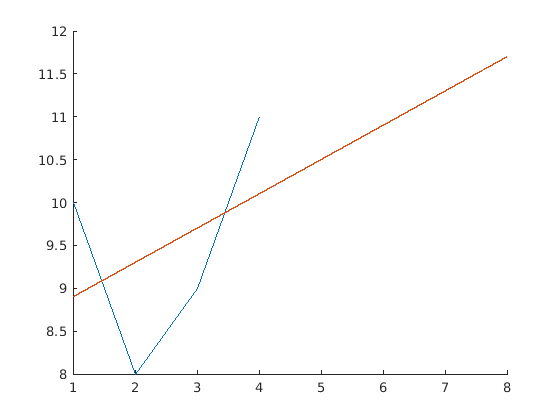


xs = linspace(1, 8, 50000);
ys = arrayfun(model, xs);

clf
hold on
plot(x, y)
plot(xs, ys)
hold off

Allgemein:

function params = fit_linear(x, y, degree)

        
$$d := degree$$


        Modellgleichung: $p(t) = \sum_{k=0}^{d}\alpha_kt ^k$

    vs = x .^ (degree:-1:0);

        Systemgleichung: $\left(\begin{array}{ccc}
x_1^d & \cdots & x_1^0\\
\vdots & & \vdots \\
x_m^d & \cdots & x_m^0\\
\end{array}\right)

\left(\begin{array}{c}
\alpha_d\\
\vdots\\
\alpha_0
\end{array}\right)

\approx y$

    [Q, R] = qr(vs);    

        Löse: $R \left( \begin{array}{c}\alpha_d\\ \vdots \\ \alpha_0 \end{array} \right) = Q^T y$

    params = R \ (Q' * y);
end

function model = fit_linear_model(x, y, degree)
    params = fit_linear(x, y, degree);
    model = @(t) (t .^ (degree:-1:0)) * params;
end